Initial parameters sizing: (ALL OF THESE HAVE TO BE DELEGATED, BUT ASSUMED FOR NOW)

The initial chosen airfoil (TOP SECRET DO NOT SHARE SG6043 [http://airfoiltools.com/airfoil/details?airfoil=sg6043-il](http://airfoiltools.com/airfoil/details?airfoil=sg6043-il)), with a Reynolds number of 50,000


clear; clc; clf; close all
R = 0.25; %Blade Radius (m)     INITIAL
R0 = 0.025; %Blade root (m)     Fixed
B = 2; %Blade number            INITIAL
TSR = 3; %Tip speed ratio       INITIAL
AoA = deg2rad(8.75); %          INITIAL

%Blade distribution             INITIAL
chord = @(r) R^2 / 3 / B / log(R / R0) / r;

This is derived from (30), solving for constant K given $A_B =K\int_{R_0 }^R \frac{1}{r}\mathrm{dr}$, then into $c\left(r\right)=\frac{K}{r}$

%Twist distribution             INITIAL
twist = @(r) atan(2 / 3 / (r / R)) - AoA;

This is from Hardik

Formulation from Burton et all 2011 Section 3.5.3 **(DO NOT SHARE, COMPANY SECRETS)**

I love this actually, its pretty cool. So how I am going to do it is assume the turbine has already started with 6000 RPM, a= 1/3 and a' = ??. I will then simulate the torque against drag on the turbine, update RPM, a and a' then repeat! That will allow me to predict the performance of this turbine.

N=10

N = 10

density = 1.225;
v_inf = 10;
a1 = 0.1;
a2 = 0.1;
v_a = 0.1; %Omega
I = 2*10^-4; % PER FIN
m = 0.03; % PER FIN

Cl = 0.5

Cl = 0.5000

Cd = 0.038

Cd = 0.0380


r_list = linspace(R0,R,N);
dr = r_list(2) - r_list(1);
dt = 0.001;

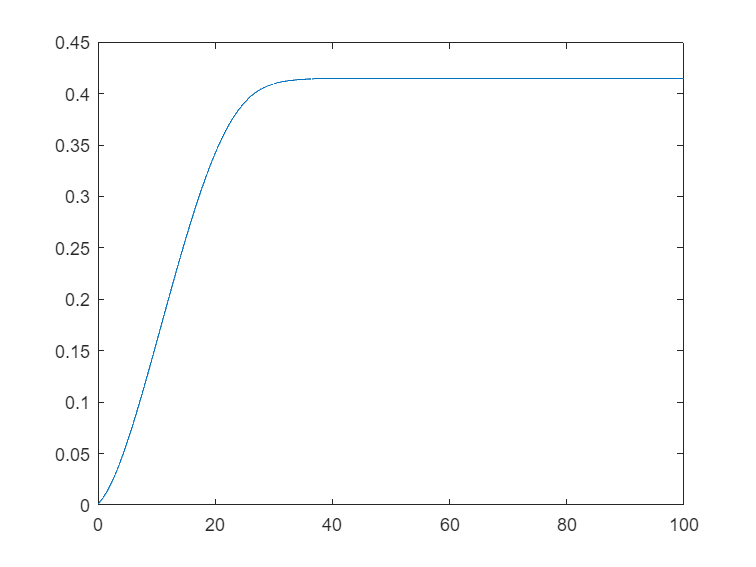

a1List = zeros(size(1:(3/dt)));
a2List = zeros(size(1:(3/dt)));
vaList = zeros(size(1:(3/dt)));
PList = zeros(size(1:(3/dt)));
for Tstep = 1:(100 / dt)
    for i = 1:5
        W = sqrt(v_inf^2 * (1 - a1)^2 + R^2 * v_a^2 * (1 + a2)^2);
        cosphi = R * v_a * (1 + a2) / W;
        sinphi = v_inf * (1 - a1) / W;
        Cx = Cl * cosphi + Cd * sinphi;
        Cy = Cl * sinphi + Cd * cosphi;
        solidity = B / (2 * pi) * chord(R) / R;
        
        eq1 = solidity * Cx / 4 / sinphi^2;
        eq2 = solidity * Cy / 4 / sinphi / cosphi;
    
        a1 = eq1 / (1 + eq1);
        a2 = eq2 / (1 + eq2);
    end
    
    Q = 0;
    for r = r_list
        Q = Q + (r/R)^2 * (8 * a2 * (1 - a1) * r / R - W / v_inf * B * chord(r) / R / pi * Cd * (1 + a2)) * dr/R;
    end
    a1List(Tstep)=a1;
    a2List(Tstep)=a2;
    vaList(Tstep)=v_a;
    PList(Tstep)=Q*v_a;
    v_a = v_a + Q / I * dt;
end
plot((0+dt):dt:100,a1List)

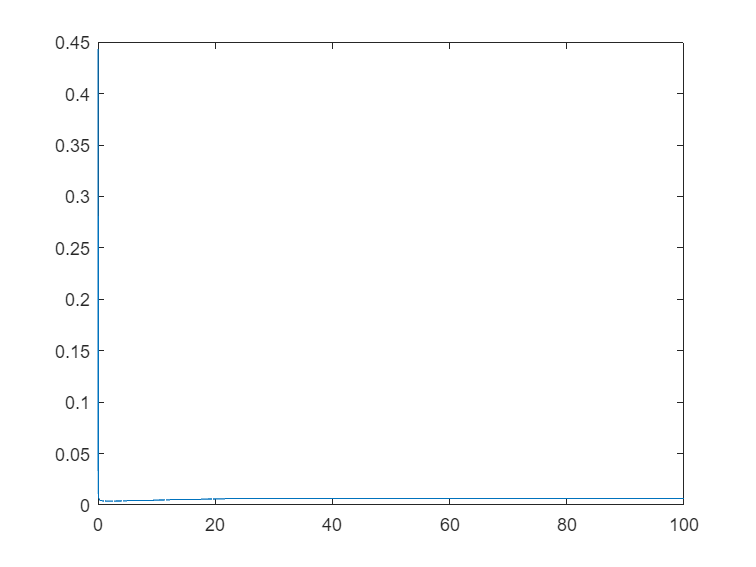

plot((0+dt):dt:100,a2List)

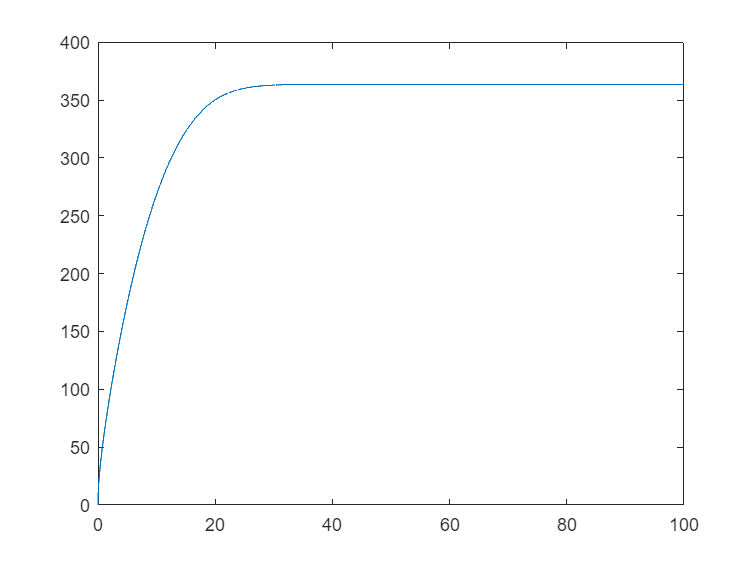

plot((0+dt):dt:100,vaList)

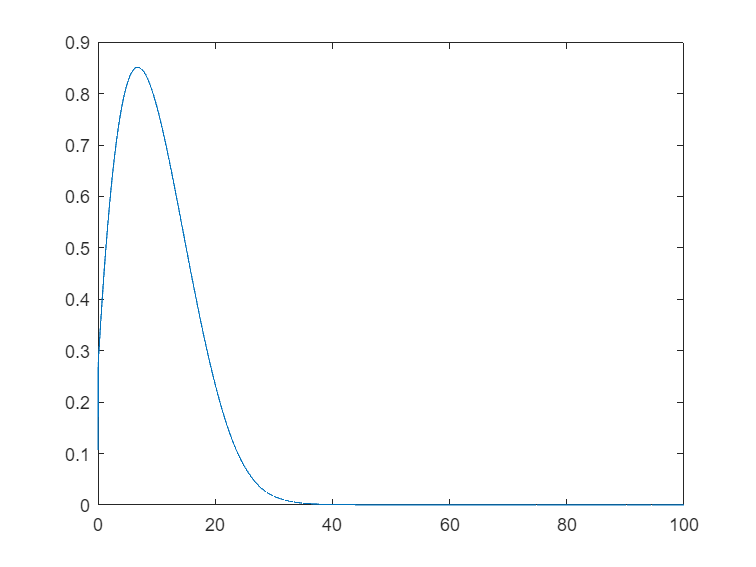

plot((0+dt):dt:100,PList)

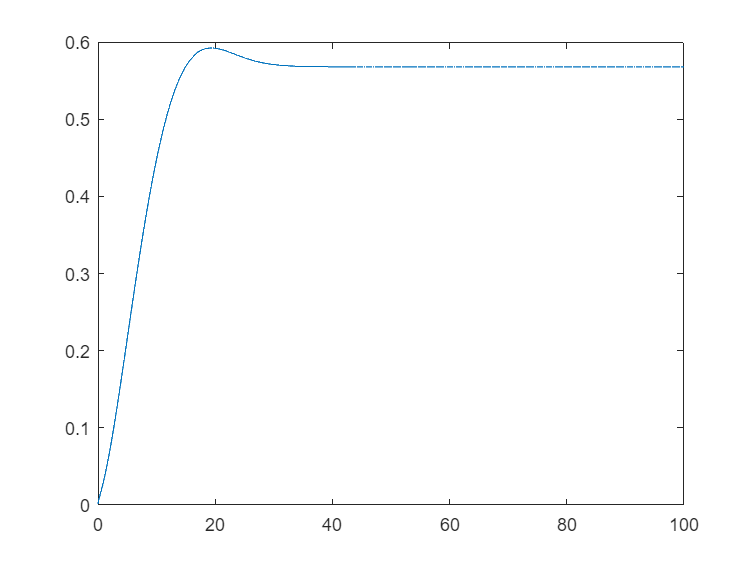

plot((0+dt):dt:100,4.*a1List.*(1-a1List).^2)

Functions